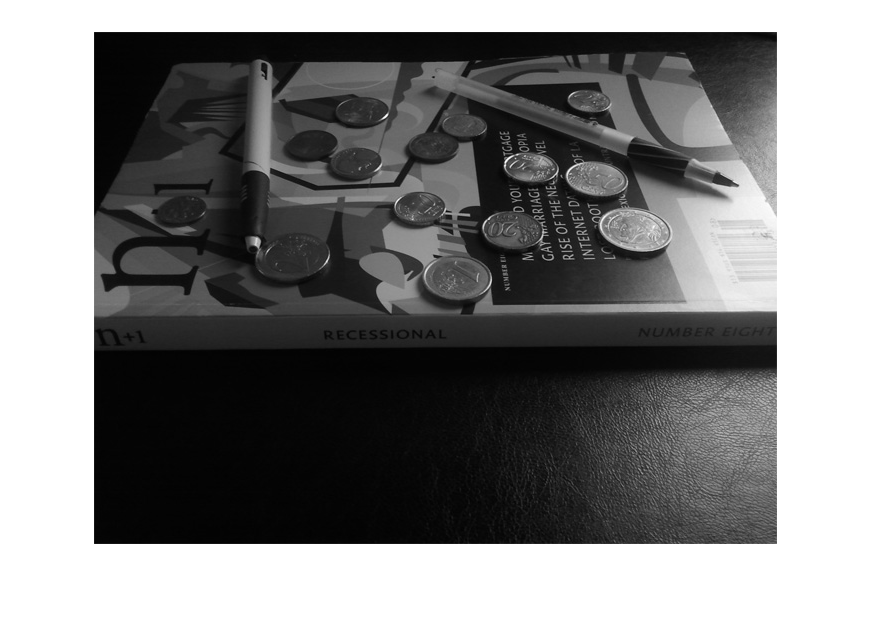

img = rgb2gray(imread("input/ps1-input3.png"));
imshow(img);

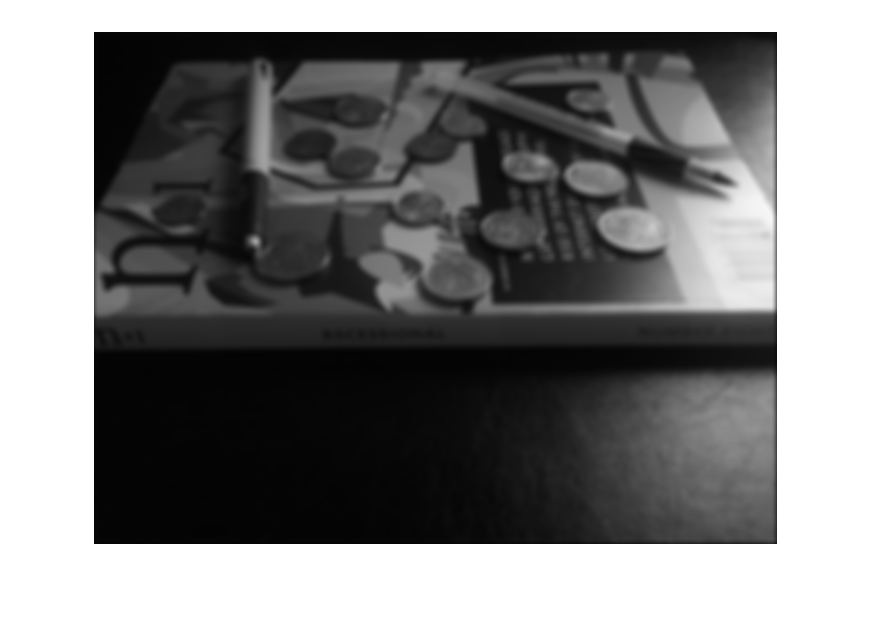

filter = fspecial('gaussian', 10,3);
img_smooth = imfilter(img, filter);
imshow(img_smooth);

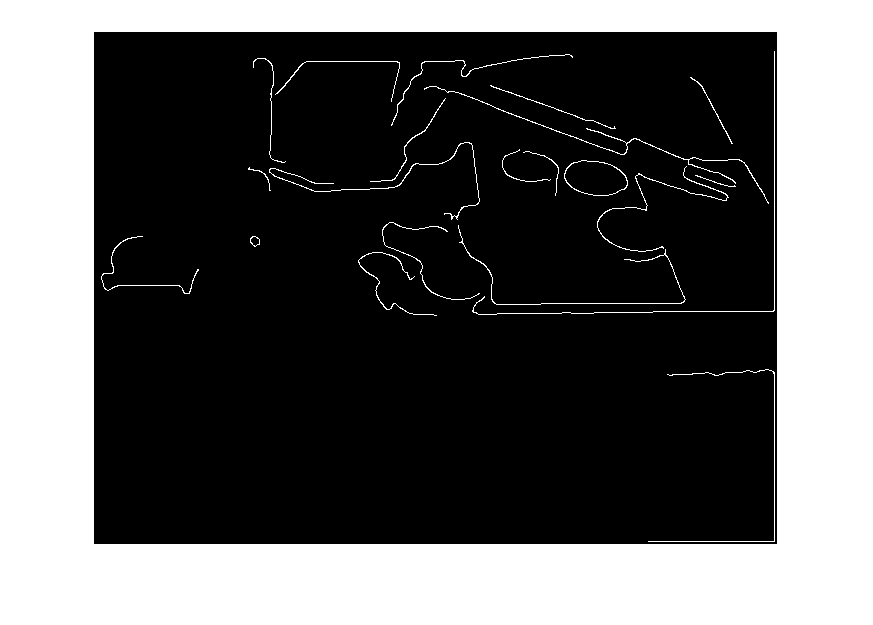

img_smooth_edges = edge(img_smooth,'Canny',0.5, "both");
imshow(img_smooth_edges);

img_edges = img_smooth_edges;


y_bins = 0:size(img_edges,1);
x_bins = 0:size(img_edges,2);
 
H = zeros(length(y_bins), length(x_bins));
radius = 20;
for r= 1: size(img_edges,1)
    for c= 1: size(img_edges,2)  
        if img_edges(r,c) == 1 
          a = c;
          b = r; 
          for x = (a-radius) : (a+radius)
              if x < 0
                  continue;
              end
              y= sqrt(radius^2 - (x-a)^2) + b;
              y_i = findbin(y_bins, y);
              x_i = findbin(x_bins, x);
              H(y_i, x_i) = H(y_i, x_i) + 1 ;
          end
       end
    end
end

imshow(H,[]);
maxH = max(H(:))

maxH = 399

[maxrowyi , maxcolxi] = find(H >= 0.3*maxH & H<=maxH);
 
a = [maxcolxi,maxrowyi]

a =    684   513


 
marks_image = insertMarker(H, a)

marks_image = marks_image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

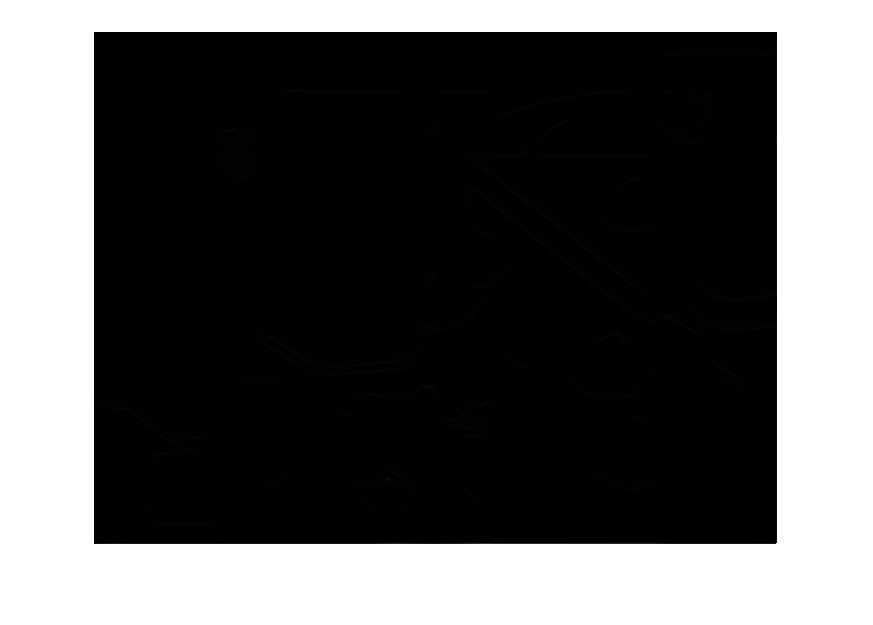

colormap gray;

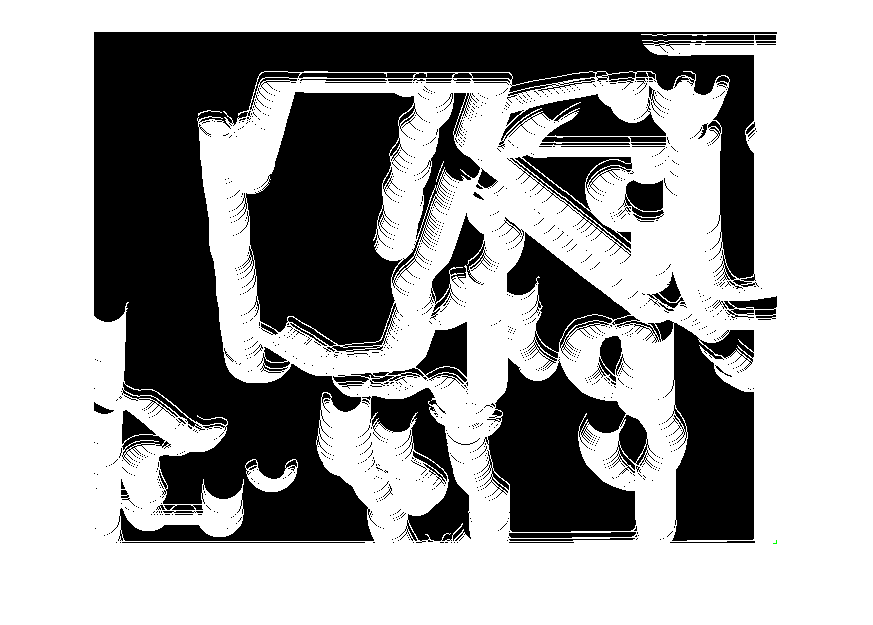

imshow(marks_image,[]);

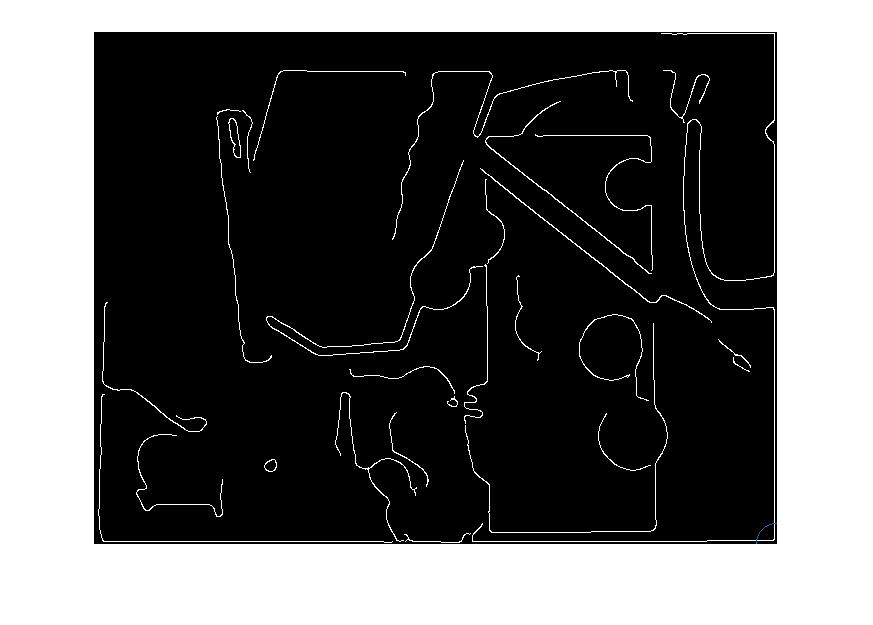

************circle1



imshow(img_edges);
for i = 1:size(a,1)
    disp("************circle"+i);
    hold on
    y = y_bins(1,a(i,2));
    x = x_bins(1,a(i,1));
    th = 0:pi/50:2*pi;
    xunit = radius * cos(th) + x;
    yunit = radius * sin(th) + y;
    h = plot(xunit, yunit);
    hold off
end